images = LoadMNISTImages('train-images.idx3-ubyte');

% for i = 1:10
% for j = 1:10
% k = (i-1)*10+j;
% subplot(10,10,k);
% temp = reshape(images(:,k),28,28);%将图像重排成28X28的尺寸
% imshow(temp,[]);
% end
% end

labels = LoadMNISTLabels('train-labels.idx1-ubyte');

images_centered = images - mean(images,2);
PCA_M = images_centered*images_centered';
[V,D] = eigs(PCA_M,784,'la'); %用eigs可以让特征值降序排列
%此时D为降序排列的特征值对角阵， V为特征向量构成的正交矩阵
images_coordinate = V'*images_centered;
%计算特征向量计算出的内积的值（注意标准正交基的性质）
images_PC = images_coordinate(1:3,:);
%提取前三行作为主成分坐标
scatter3(images_PC(1,:),images_PC(2,:),images_PC(3,:),[],labels,'.');
%三维点状图示，每一种数字的点对应一种颜色
colormap hsv,colorbar

images_train=LoadMNISTImages('train-images.idx3-ubyte');
images_test=LoadMNISTImages('t10k-images.idx3-ubyte');
labels_train=LoadMNISTLabels('train-labels.idx1-ubyte');
labels_test=LoadMNISTLabels('t10k-labels.idx1-ubyte');

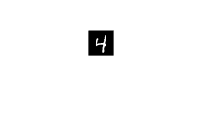

test_image = images_test(:,20);
temp1 = reshape(images_test(:,20),28,28);
imshow(temp1,[])

x_diff = images_train - test_image;
%计算训练集和该图像的差距
x_dist = sqrt(sum(x_diff.*x_diff));
%根据差距计算出欧氏距离
[~,x_ranking] = sort(x_dist);
%排序，无需返回排序后的序列，只返回排序后从小到大的列指标
KNN_labels = labels_train(x_ranking(1:30));
KNN_labels'

ans =      4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     9     4     4


GroundTruth_label = labels_test(20)

GroundTruth_label = 4

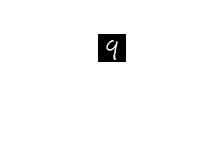

temp2 = reshape(images_train(:,x_ranking(28)),28,28);
imshow(temp2,[])

Correct_Count = 0;
for j = 1:10000
x_diff = images_train - images_test(:,j);
x_dist = sqrt(sum(x_diff.*x_diff));
[~,x_ranking] = sort(x_dist);
KNN_labels = labels_train(x_ranking(1:20));
%最近的20个标签不同时，需要做出合理的决策，如何综合利用KNN数据，为该类方法带来了很多的变化
temp = zeros(1,10);
for i = 1:20
temp(KNN_labels(i)+1) = temp(KNN_labels(i)+1) + (21-i);%一种粗糙评分，最近的评20分，第二近的19分，以此类推
end
[~,Final_label] = max(temp); %寻找得分最高的数字
Final_label = Final_label - 1; %不要忘记减1代表0-9
GroundTruth_label = labels_test(j);
if(Final_label == GroundTruth_label)
Correct_Count = Correct_Count + 1;
end
end
Correct_rate = Correct_Count/10000;

Correct_rate

Correct_rate = 0.9660